Open File and create table

format short
f = fopen("iiris data/iris.data","r");
sdata = fscanf(f,"%c");
final = split(sdata,newline);
final = split(final(1:150),',');
data = (str2double(final(:,1:4)));
data_set = str2double(final(strcmpi(final(:,5),'Iris-setosa') ~= 0,1:4));
data_ver = str2double(final(strcmpi(final(:,5),'Iris-versicolor') ~= 0,1:4));
data_vir = str2double(final(strcmpi(final(:,5),'Iris-virginica') ~= 0,1:4));
%data = data_vir;

preprocessing

m = mean(data);
sd = std(data,0);
updata = (data - m) ./ sd;

co-variance

cv = cov(updata); %(data' * data) / 149

singular value decomposition

[u, s, v] = svd(cv);

projecting and displaying

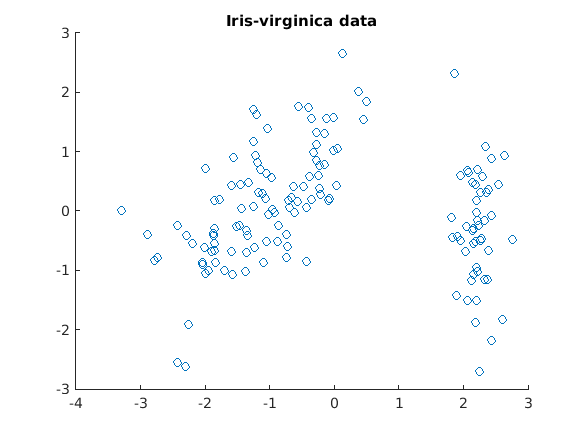

proj = updata * u;
scatter(proj(:,1)',proj(:,2)')
title("Iris-virginica data")

data retrival and error

final = proj(:,1:2) * (u(:,1:2))';
final = final .* sd;
final = final+m;
meanerror  = mean(data - final)

meanerror = 	1.0e+-15 *

    0.1421   -0.0118   -0.8556    0.2679
